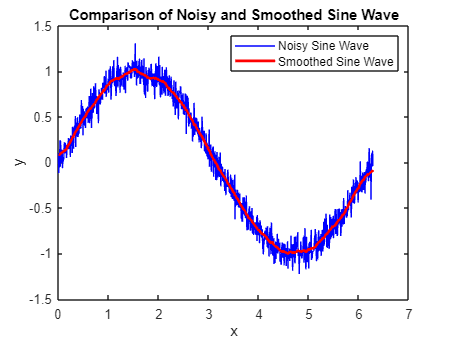

% Number of points
N = 1000;

% Generate the x-axis values (one complete cycle)
x = linspace(0, 2*pi, N);

% Generate the sine wave
y = sin(x);

% Add random noise to the sine wave
noiseAmplitude = 0.1;
yNoisy = y + noiseAmplitude * randn(size(y));

% Define the window size for the moving average
windowSize = 50;  % Adjust based on desired smoothness

% Apply the moving average filter using built-in function
ySmoothed = smoothdata(yNoisy, 'movmean', windowSize);

% Plot the results
figure;
plot(x, yNoisy, 'b-', 'DisplayName', 'Noisy Sine Wave');
hold on;
plot(x, ySmoothed, 'r-', 'LineWidth', 2, 'DisplayName', 'Smoothed Sine Wave');
legend show;
xlabel('x');
ylabel('y');
title('Comparison of Noisy and Smoothed Sine Wave');


% Save data to CSV
data = [yNoisy]'; 
csvwrite('sine_wave_data.csv', data);